Øvelse 1

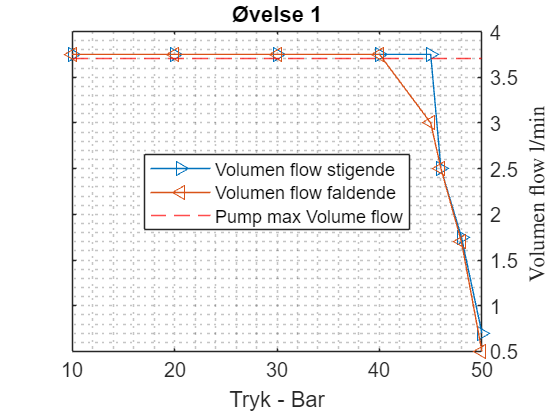

clear all
clf

Tryk = [10 20 30 40 45 46 48 50];
VolumenFlow_op = [3.75 3.75 3.75 3.75 3.75 2.5 1.75 0.7];
VolumenFlow_ned = [3.75 3.75 3.75 3.75 3.0 2.5 1.7 0.5];

plot(Tryk, VolumenFlow_op, '>-', Displayname="Volumen flow stigende")
hold on
plot(Tryk, VolumenFlow_ned, '<-', Displayname="Volumen flow faldende")
yline(3.7, 'r--', DisplayName="Pump max Volume flow")
title('Øvelse 1')
ylabel("Volumen flow l/min ", Interpreter="latex")
xlabel("Tryk - Bar")
grid("minor")
legend(Location="best")
set(gca, 'YAxisLocation', 'right');
hold off

Beregn pumpens fortrængning [cm3/rev]

flow = 3.7 * 10 * 10 * 10 % L/min * cm^3/L = cm^3/min

flow = 3700

RPM = 1415; %rpm

V_th = flow / RPM %  cm^3/min * min/rev = cm^3/rev % fortrængning

V_th = 2.6148


VolumenFlow_medium = (VolumenFlow_op(end) + VolumenFlow_ned(end) )/2

VolumenFlow_medium = 0.6000

V_th_50 = VolumenFlow_medium * 10 * 10 * 10 / RPM %  cm^3/min * min/rev = cm^3/rev % fortrængning 50 bar

V_th_50 = 0.4240


eta_vol = V_th_50/V_th *100 % Volumetrisk volumetriske virkningsgrad ved [50 bar].

eta_vol = 16.2162

Øvelse 2

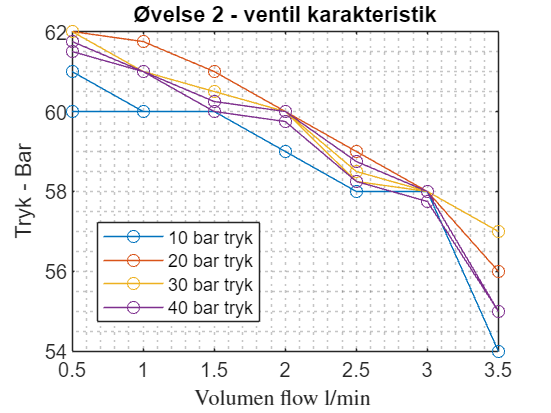

clear all
clf

VolumenFlow = [0.5 1.0 1.5 2.0 2.5 3.0 3.5 3.0 2.5 2.0 1.5 1.0 0.5];
Tryk_10 = [61 60 60 59 58 58 54 58 58 59 60 60 60];
Tryk_20 = [62 61.75 61 60 59 58 56 58 59 60 60.5 61 62];
Tryk_30 = [62 61 60.5 60 58.25 58 57 58 58.5 60 60.5 61 62 ];
Tryk_40 = [61.75 61 60 59.75 58.25 57.75 55 58 58.75 60 60.25 61 61.5 ];

plot(VolumenFlow, Tryk_10, 'o-', Displayname="10 bar tryk")
hold on
plot(VolumenFlow, Tryk_20, 'o-', Displayname="20 bar tryk")
plot(VolumenFlow, Tryk_30, 'o-', Displayname="30 bar tryk")
plot(VolumenFlow, Tryk_40, 'o-', Displayname="40 bar tryk")
title('Øvelse 2 - ventil karakteristik')
xlabel("Volumen flow l/min ", Interpreter="latex")
ylabel("Tryk - Bar")
grid("minor")
legend(Location="best")
hold off

Øvelse 3

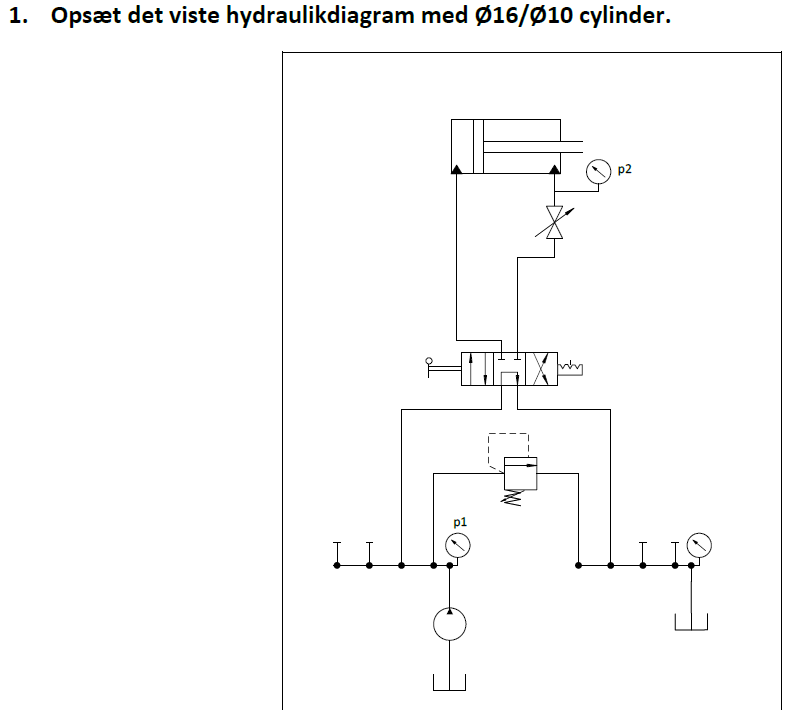

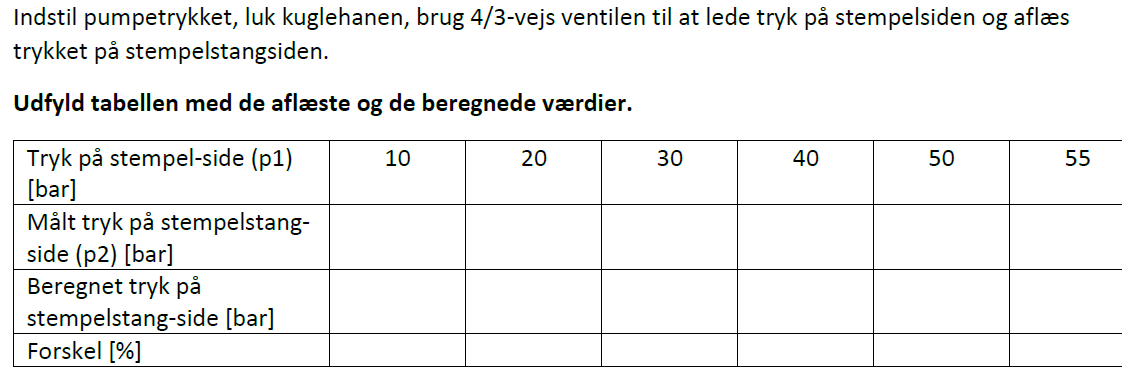

d1 = 0.016;
d2 = 0.010;
A1 = pi*(d1/2)^2

A1 = 2.0106e-04

A2 = pi*(d2/2)^2

A2 = 7.8540e-05

c = A1/A2 % areal forskel

c = 2.5600

clf

Opgave 1.

Trykp1 = [10 20 30 40 50 55];
Trykp2_16_10 = [15 30 46 62 78 86]; % 152857
Trykp2_16_10_calc = c * Trykp1

Trykp2_16_10_calc =    25.6000   51.2000   76.8000  102.4000  128.0000  140.8000



forskel_1 = (Trykp2_16_10_calc - Trykp2_16_10)./Trykp2_16_10_calc * 100

forskel_1 =    41.4063   41.4063   40.1042   39.4531   39.0625   38.9205


Opgave 2.

clear
d1 = 0.025;
d2 = 0.018;
A1 = pi*(d1/2)^2

A1 = 4.9087e-04

A2 = pi*(d2/2)^2

A2 = 2.5447e-04

c2 = A1/A2 % areal forskel

c2 = 1.9290


Trykp2 = [10 20 30 40 50];
Trykp2_25_18 = [19 36 54 70 92]; % 184490

Trykp2_25_18_calc = c2 * Trykp2

Trykp2_25_18_calc =    19.2901   38.5802   57.8704   77.1605   96.4506



forskel_2 = (Trykp2_25_18_calc - Trykp2_25_18)./Trykp2_25_18_calc * 100

forskel_2 =     1.5040    6.6880    6.6880    9.2800    4.6144


Opgave 3.

clear
d1 = 0.016;
d2 = 0.010;
A1 = pi*(d1/2)^2

A1 = 2.0106e-04

A2 = pi*(d2/2)^2

A2 = 7.8540e-05

c = A2/A1 % areal forskel

c = 0.3906


Trykp3 = [10 20 30 40 50 60];
Trykp2_16_10 = [9 16 18 23 29 34]; % 152857

Trykp2_16_10_calc = Trykp3%c * Trykp3

Trykp2_16_10_calc =     10    20    30    40    50    60



forskel_3 = (Trykp2_16_10_calc - Trykp2_16_10)./Trykp2_16_10_calc * 100

forskel_3 =    10.0000   20.0000   40.0000   42.5000   42.0000   43.3333


Opgave 4. Opsæt det viste hydraulikdiagram med Ø16/Ø10 cylindr

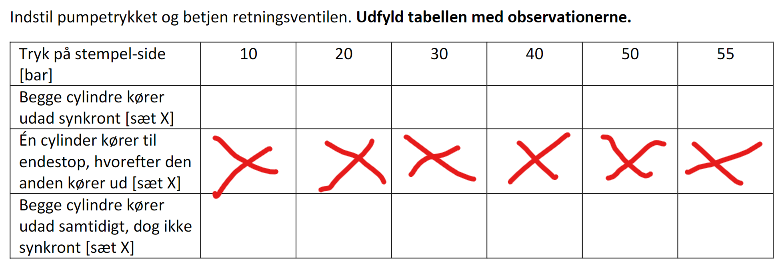


d3 = 0.025;
d4 = 0.018;
A3 = pi*(d3/2)^2

A3 = 4.9087e-04

A4 = pi*(d4/2)^2

A4 = 2.5447e-04

Trykp2_25_18 = [19 36 54 70 92];

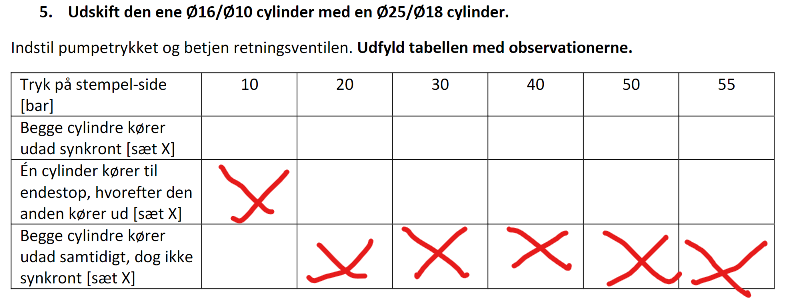

6.

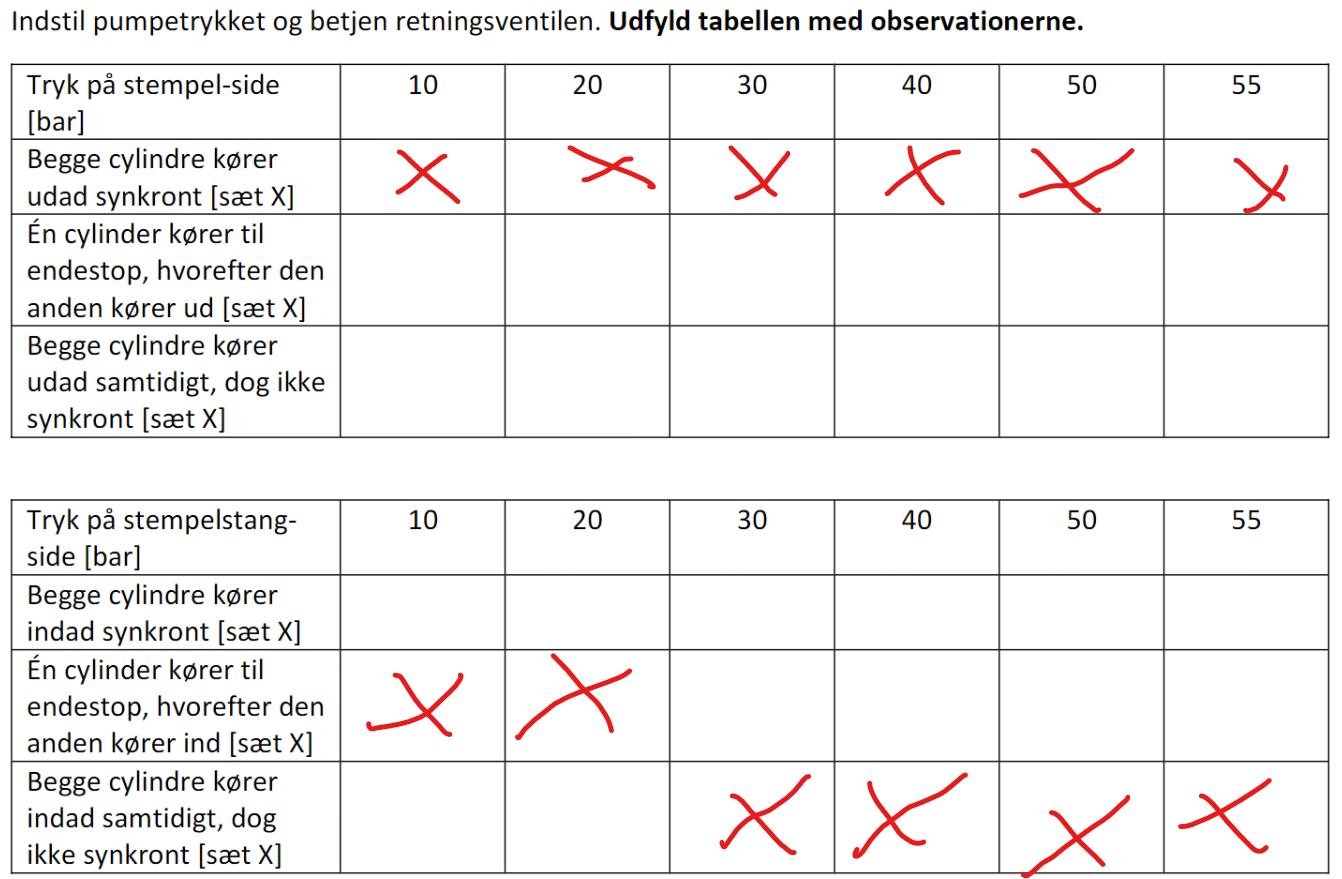

Øvelse 4

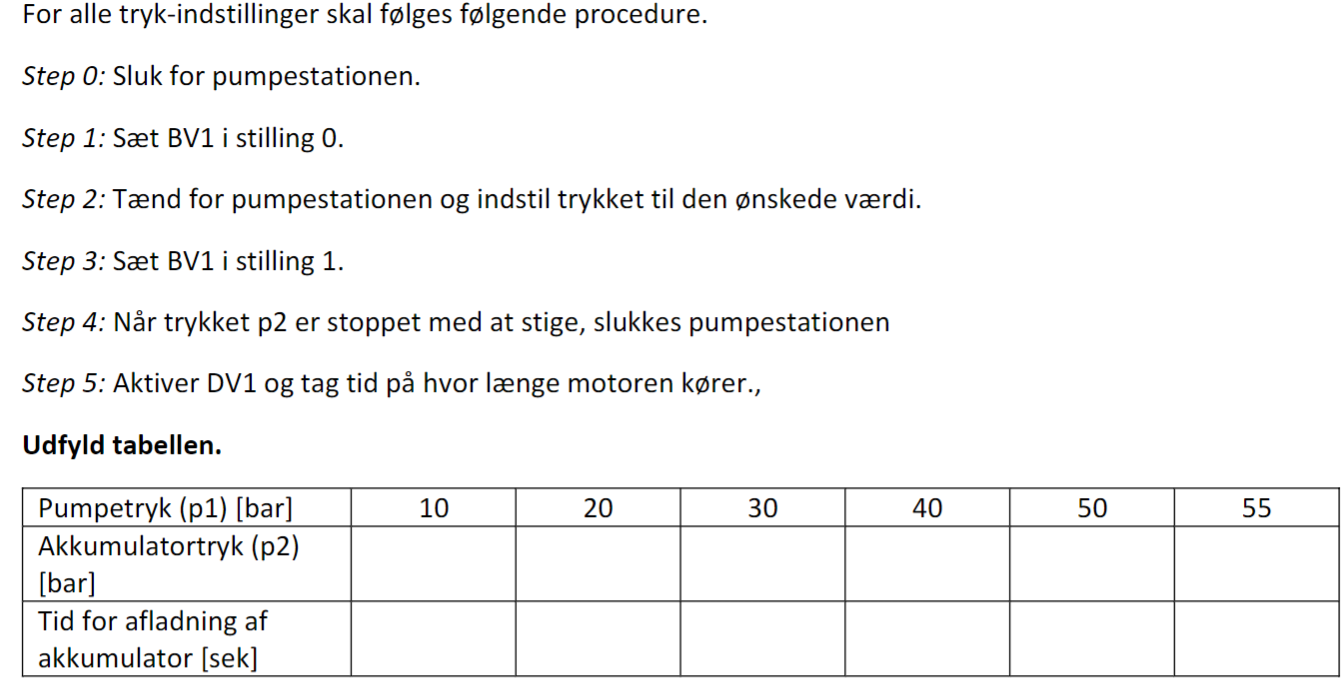

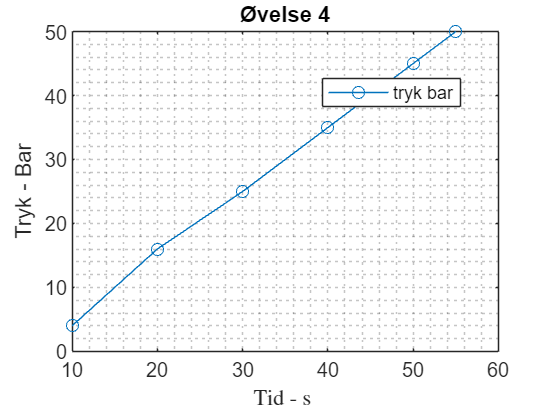

Tryk_p1 = [10 20 30 40 50 55];

Tryk_p2 = [4 16 25 35 45 50];
Tid = [0.1 1.5 3.6 5.8 7.1 7.7];

plot(Tryk_p1, Tryk_p2, 'o-', Displayname="tryk bar")
hold on
title('Øvelse 4')
xlabel("Tid - s ", Interpreter="latex")
ylabel("Tryk - Bar")
grid("minor")
legend(Location="best")
hold off

Øbelse 5

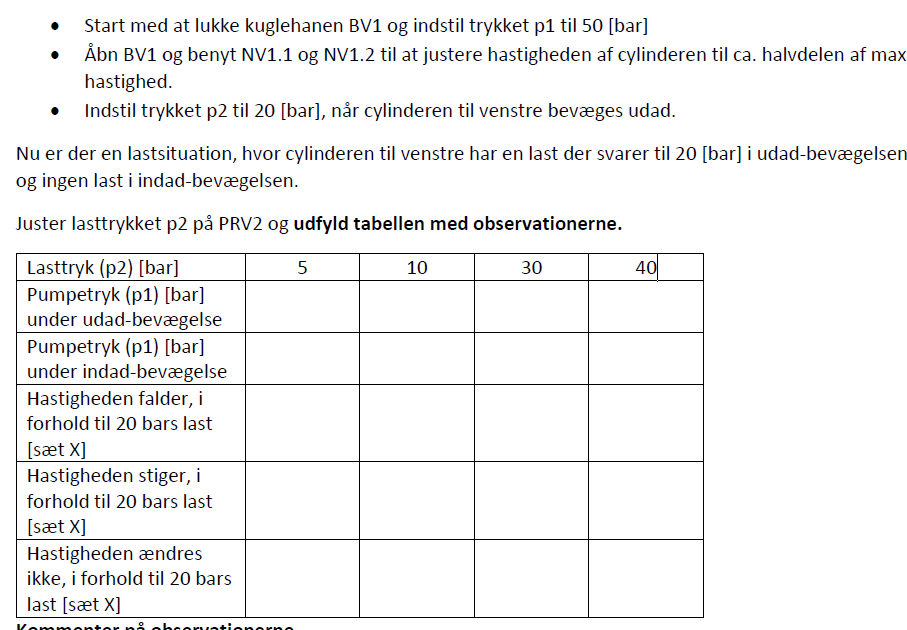

Lasttryk_p2 = [5 10 30 40];
Pumpetryk_P1_ud =[48 48 48 49]

Pumpetryk_P1_ud =     48    48    48    49


Pumpetryk_P1_ind =[48 48 48 48]

Pumpetryk_P1_ind =     48    48    48    48


Pumpetryk_P3_ud =[0 0 0 0]

Pumpetryk_P3_ud =      0     0     0     0


Pumpetryk_P3_ind =[11.5 12 12 14]

Pumpetryk_P3_ind =    11.5000   12.0000   12.0000   14.0000


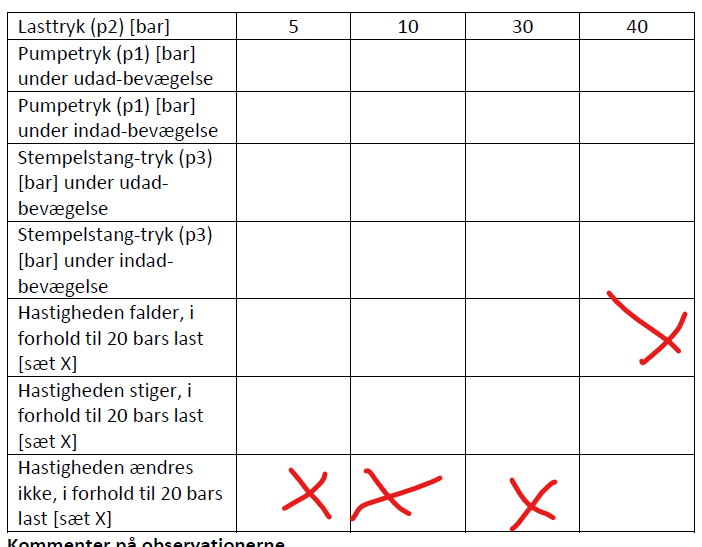    

Lasttryk_p2 = [5 10 30 38]; % kan ikke nå 40
Pumpetryk_P1_ud =[15 20 40 45]

Pumpetryk_P1_ud =     15    20    40    45


Pumpetryk_P1_ind =[48 48 48 48]

Pumpetryk_P1_ind =     48    48    48    48


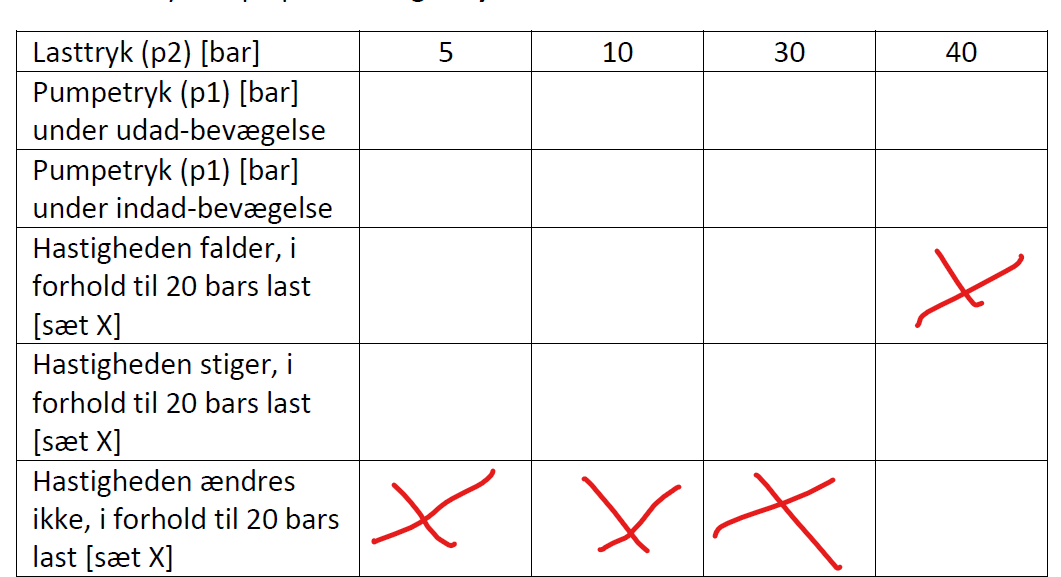

Lasttryk_p2 = [5 10 30 39];
Pumpetryk_P1_ud =[19 21 40 44]

Pumpetryk_P1_ud =     19    21    40    44


Pumpetryk_P1_ind =[48 48 48 48]

Pumpetryk_P1_ind =     48    48    48    48


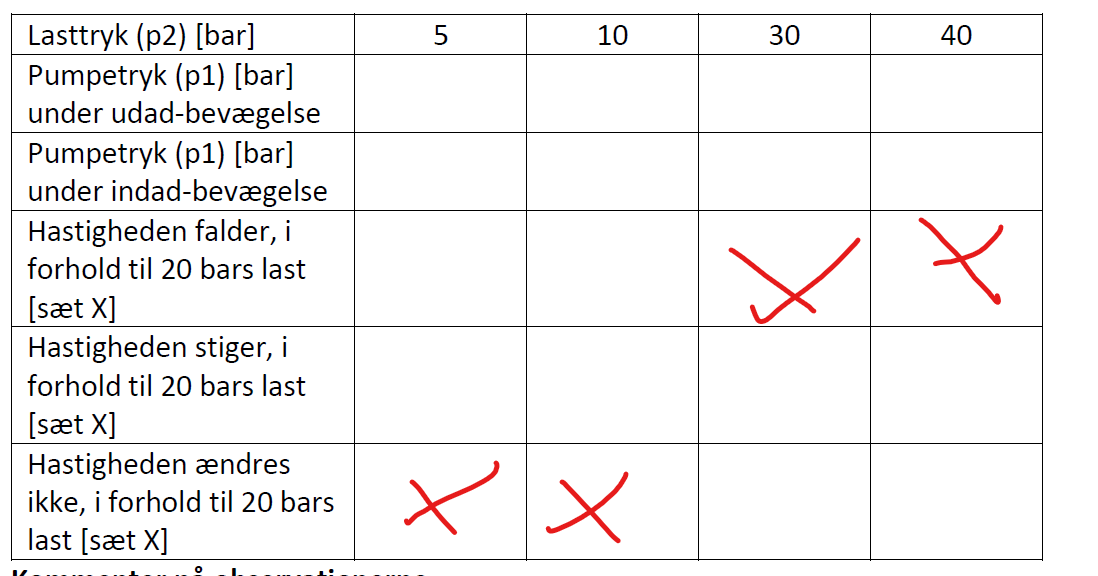

1. Hvilken type hastighedskontrol (meter in eller meter out) er det på bevægelsen udad?

Der skal srues ud på flow restrictions ventilen NV1.1

DV1.1 trykkes til venstre

2. Hvilken type hastighedskontrol (meter in eller meter out) er det på bevægelsen indad?

Der skal srues ud på flow restrictions ventilen NV1.2

3. Hvad sker der når DV1.1 og og DV1.2 er aktiveret samtidigt under bevægelsen udad?

Den bliver langsommer

4. Hvad sker der når DV1.1 og og DV1.2 er aktiveret samtidigt under bevægelsen indad?

Denkøre alimindelige hastighed ind af

DV1.2 er sat op som en såkaldt ”ilgangsventil”, som er ofte brugt på diverse maskiner, ofte er funktionen bygget ind som en fjerde stilling på DV1.1.

5. Optegn en retningsventil med ilgangsfunktion i den fjerde stilling.

6. Hvad type retningsventil er den tegnede retningsventil?